A.) In class, we made a plot relating the concentration of a molecular species inside *E. coli* to the absolute number of those molecules.  Expand your code in order to plot this relation for *E. coli*, a nucleus of the early embryo of the fruit fly, a yeast cell, and your favorite cell type.  Remember to label your axis and all lines!

By Hannah Verdonk

The benchmark numbers of molecules:

x=[1,5,10,50,100,500,1000]; %Number of molecules

The formula for concentration is #molecules/Cell_Volume. All volumes are in fL.

eColi = x/1;           %class
fruitFly = x/78;       %BNID 101397
yeast = x/7;           %S. cerevisiae BNID 114949
oocyte = x/4000000;    %human oocyte BNID 101664

This is the plot of the number of molecules vs molecular concentration for the four different cell types.

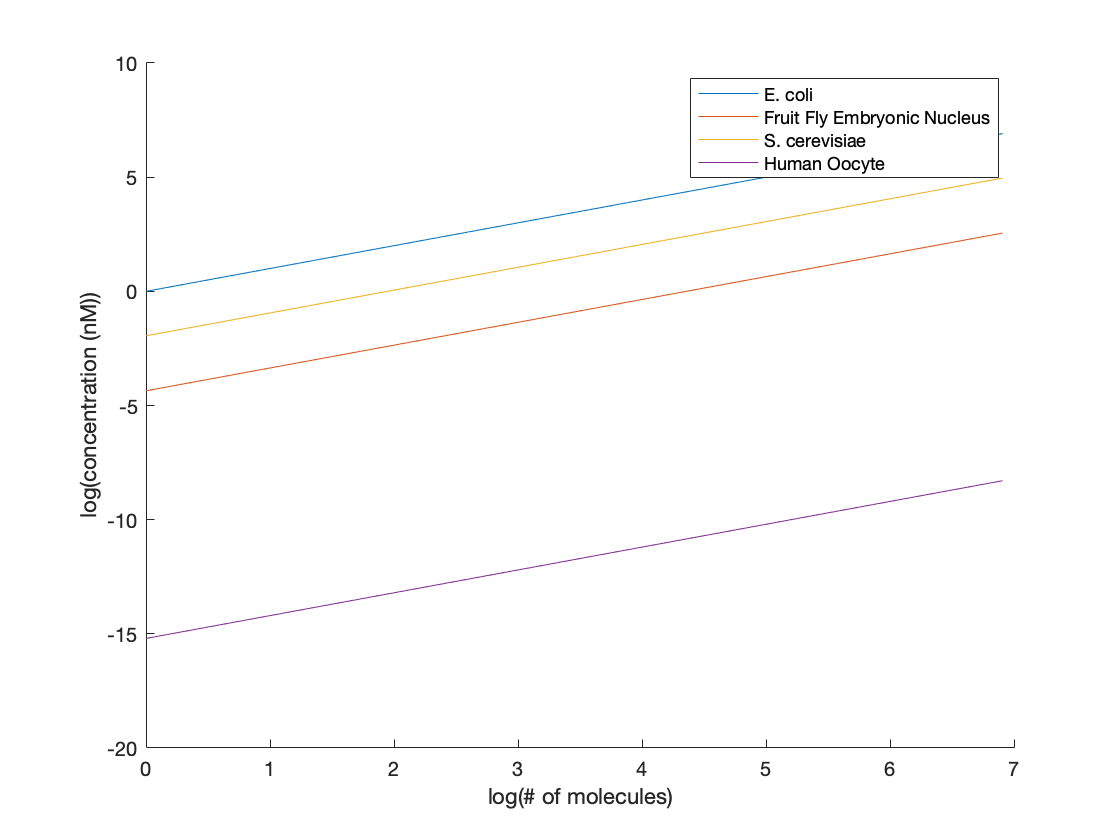

x=log(x);
eColi=log(eColi);
fruitFly=log(fruitFly);
yeast=log(yeast);
oocyte=log(oocyte);


figure; hold on
a1=plot(x, eColi); M1='E. coli';
a2=plot(x, fruitFly); M2='Fruit Fly Embryonic Nucleus';
a3=plot(x, yeast); M3='S. cerevisiae';
a4=plot(x, oocyte); M4='Human Oocyte';

legend([a1;a2;a3;a4], M1,M2,M3,M4);
xlabel('log(# of molecules)');
ylabel('log(concentration (nM))');

hold off